% Updated model
  
ds = datastore("3008318mod.csv","TextType","string","DatetimeType","datetime");

preview(ds);
ds.ReadSize;
%data1 = read(ds);
WS = readall(ds);
ws = removevars(WS,["AWND","AWND_1","AWND_2","AWND_3","AWND_4","AWND_5","AWND_6","AWND_7",...
    "DATE_1","DATE_2","DATE_3","DATE_4","DATE_5","DATE_6","DATE_7","FMTM","FMTM_1","FMTM_2","FMTM_3","FMTM_4","FMTM_5","FMTM_6","FMTM_7",...
    "MDPR","MDPR_1","MDPR_2","MDPR_3","MDPR_4","MDPR_5","MDPR_6","MDPR_7","NAME","NAME_1","NAME_2","NAME_3","NAME_4","NAME_5","NAME_6","NAME_7",...
    "PGTM","PGTM_1","PGTM_2","PGTM_3","PGTM_4","PGTM_5","PGTM_6","PGTM_7","PRCP",...
    "PRCP_1","PRCP_2","PRCP_3","PRCP_4","PRCP_5","PRCP_6","PRCP_7","PSUN","PSUN_1","PSUN_2","PSUN_3","PSUN_4",...
    "PSUN_5","PSUN_6","PSUN_7","SNOW","SNOW_1","SNOW_2","SNOW_3","SNOW_4","SNOW_5","SNOW_6","SNOW_7","SNWD",...
    "SNWD_1","SNWD_2","SNWD_3","SNWD_4","SNWD_5","SNWD_6","SNWD_7","TSUN","TSUN_1","TSUN_2","TSUN_3","TSUN_4","TSUN_5","TSUN_6","TSUN_7",...
    "WDF2","WDF2_1","WDF2_2","WDF2_3","WDF2_4","WDF2_5","WDF2_6","WDF2_7","WDF5","WDF5_1","WDF5_2","WDF5_3","WDF5_4","WDF5_5","WDF5_6","WDF5_7",...
    "WESD","WESD_1","WESD_2","WESD_3","WESD_4","WESD_5","WESD_6","WESD_7","WSF5","WSF5_1","WSF5_2","WSF5_3","WSF5_4","WSF5_5","WSF5_6","WSF5_7",...
    "WT01","WT01_1","WT01_2","WT01_3","WT01_4","WT01_5","WT01_6","WT01_7","STATION","STATION_1","STATION_2","STATION_3","STATION_4","STATION_5","STATION_6","STATION_7",...
    "WSF2","WSF2_1","WSF2_2","WSF2_3","WSF2_4","WSF2_5","WSF2_6","WSF2_7","WT02","WT02_1","WT02_2","WT02_3","WT02_4","WT02_5","WT02_6","WT02_7",...
    "WT03","WT03_1","WT03_2","WT03_3","WT03_4","WT03_5","WT03_6","WT03_7","WT04","WT04_1","WT04_2","WT04_3","WT04_4","WT04_5","WT04_6","WT04_7",...
    "WT05_1","WT05_2","WT05_3","WT05_4","WT05_5","WT05_6","WT05_7","WT06_1","WT06_2","WT06_3","WT06_4","WT06_5","WT06_6","WT06_7","WT07_1","WT07_2",...
    "WT07_3","WT07_4","WT07_5","WT07_6","WT07_7","WT08_1","WT08_2","WT08_3","WT08_4","WT08_5","WT08_6","WT08_7","WT09_1","WT09_2","WT09_3","WT09_4",...
    "WT09_5","WT09_6","WT09_7","WT10_1","WT10_2","WT10_3","WT10_4","WT10_5","WT10_6","WT10_7","WT11_1","WT11_2","WT11_3","WT11_4","WT11_5","WT11_6",...
    "WT11_7","WT13_1","WT13_2","WT13_3","WT13_4","WT13_5","WT13_6","WT13_7","WT14_1","WT05","WT06","WT07","WT08","WT09","WT10","WT11","WT13","WT14","WT15","WT16","WT17","WT18","WT19","WT21","WT22",...
    "WT14_2","WT14_3","WT14_4","WT14_5","WT14_6","WT14_7","WT15_1","WT15_2","WT15_3","WT15_4","WT15_5","WT15_6","WT15_7","WT16_1","WT16_2","WT16_3",...
    "WT16_4","WT16_5","WT16_6","WT16_7","WT17_1","WT17_2","WT17_3","WT17_4","WT17_5","WT17_6","WT17_7","WT18_1","WT18_2","WT18_3","WT18_4","WT18_5",...
    "WT18_6","WT18_7","WT19_1","WT19_2","WT19_3","WT19_4","WT19_5","WT19_6","WT19_7","WV01_1","WV01_2","WV01_3","WV01_4","WV01_5","WV01_6","WV01_7",...
    "WV03_1","WV03_2","WV03_3","WV03_4","WV03_5","WV03_6","WV03_7","WT21_1","WT21_2","WT21_3","WT21_4","WT21_5","WT21_6","WT21_7","WT22_1","WT22_2",...
    "WT22_3","WT22_4","WT22_5","WT22_6","WT22_7","WV03","WV01"...
    ]);
% Fill NaN T Average values with recalculated averages 
ws.TAVG = (ws.TMAX + ws.TMIN)./2;ws.TAVG_1 = (ws.TMAX_1 + ws.TMIN_1)./2;ws.TAVG_2 = (ws.TMAX_2 + ws.TMIN_2)./2;
ws.TAVG_3 = (ws.TMAX_3 + ws.TMIN_3)./2;ws.TAVG_4 = (ws.TMAX_4 + ws.TMIN_4)./2;ws.TAVG_5 = (ws.TMAX_5 + ws.TMIN_5)./2;
ws.TAVG_6 = (ws.TMAX_6 + ws.TMIN_6)./2;ws.TAVG_7 = (ws.TMAX_7 + ws.TMIN_7)./2;

%Train data
ws1 = ws(1:1534,:);
% Test data
ws2 = ws(1535:2191,:);


%   FAIRBANKS INTERNATIONAL AIRPORT, AK US
% 1 HUNTSVILLE MUNICIPAL AIRPORT, TX US
% 2 KANSAS CITY DOWNTOWN AIRPORT, MO US
% 3 ISLIP LI MACARTHUR AIRPORT, NY US
% 4 KALISPELL GLACIER AIRPORT, MT US
% 5 CARLSBAD MCCLELLAN PALOMAR AIRPORT, CA US
% 6 HONOLULU INTERNATIONAL AIRPORT, HI US
% 7 ANDERSON FAA AIRPORT, SC US

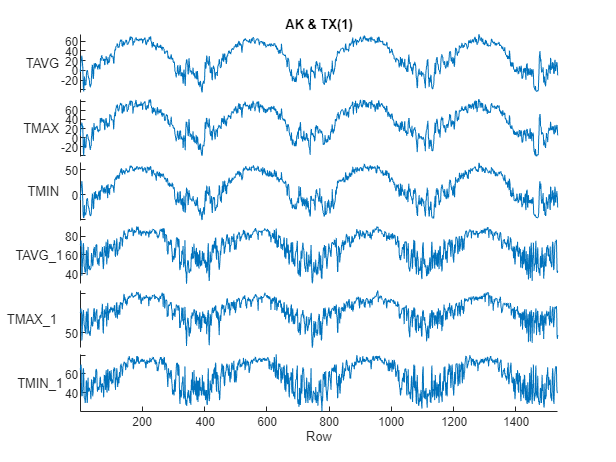

 
%   FAIRBANKS INTERNATIONAL AIRPORT, AK US
% 1 HUNTSVILLE MUNICIPAL AIRPORT, TX US
stackedplot(ws1(:,2:7))
title("AK & TX(1)")

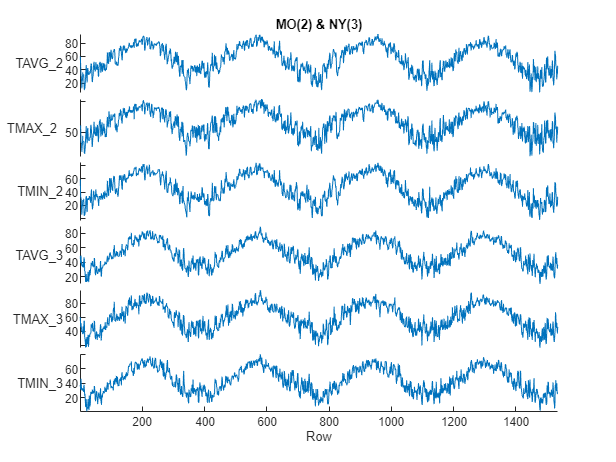

% 2 KANSAS CITY DOWNTOWN AIRPORT, MO US
% 3 ISLIP LI MACARTHUR AIRPORT, NY US
stackedplot(ws1(:,8:13))
title("MO(2) & NY(3)")

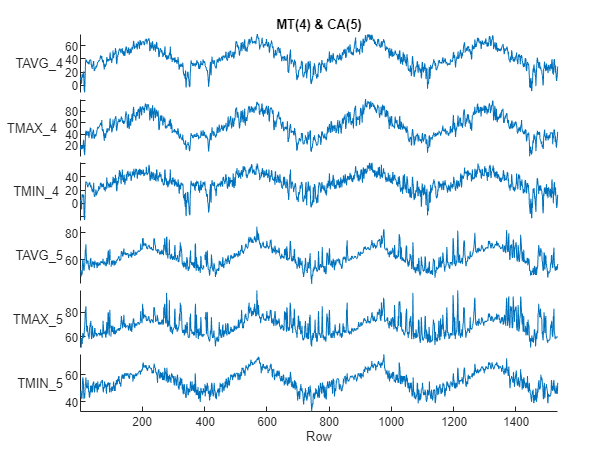


% 4 KALISPELL GLACIER AIRPORT, MT US
% 5 CARLSBAD MCCLELLAN PALOMAR AIRPORT, CA US
stackedplot(ws1(:,14:19))
title("MT(4) & CA(5)")

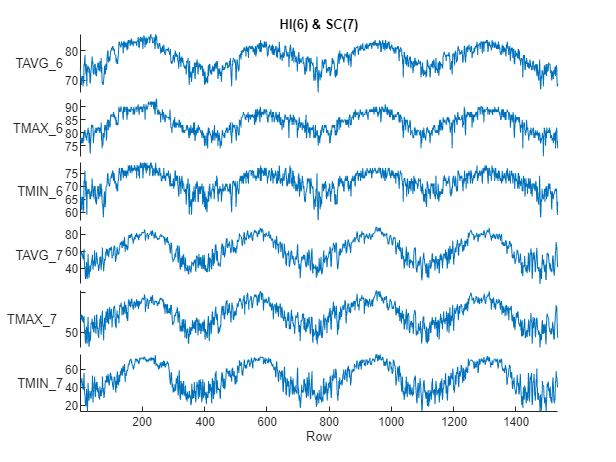


% 6 HONOLULU INTERNATIONAL AIRPORT, HI US
% 7 ANDERSON FAA AIRPORT, SC US
stackedplot(ws1(:,20:25))
title ("HI(6) & SC(7)")

 
% Predicting T average from Tmax and Tmin

% RQ GPR
% Average Temperature
[trmdl1, vRMSE1] = tavgRMrqGPR(ws1);
yft1 = trmdl1.predictFcn(ws2);
er1 = yft1 - ws2.TAVG_2;

% Max Temperature
[trmdl2, vRMSE2] = tmaxRMrqGPR(ws1);
yft2 = trmdl2.predictFcn(ws2);
er2 = yft2 - ws2.TAVG_2;

[trmdl3, vRMSE3] = tmaxRMexpGPR(ws1);
yft3 = trmdl3.predictFcn(ws2);
er3 = yft3 - ws2.TAVG_2;

% Min Temperature
[trmdl4, vRMSE4] = tminRMrqGPR(ws1);
yft4 = trmdl4.predictFcn(ws2);
er4 = yft4 - ws2.TAVG_2;
% Min Temp: Exp GPR
[trmdl5, vRMSE5] = tminRMexpGPR(ws1);
yft5 = trmdl5.predictFcn(ws2);
er5 = yft4 - ws2.TAVG_2;

RMSE = [vRMSE1,vRMSE2,vRMSE3,vRMSE4,vRMSE5];yft = [yft1,yft2,yft3,yft4,yft5];err = [er1,er2,er3,er4,er5];
tmax = (yft2+yft3)./2;tmin = (yft4+yft5)./2;tmaxtminavg = (tmax+tmin)./2;

Predictiondata2 = table(ws2.TAVG_2,yft2,yft3,yft4,yft5);
Predictiondata2.Properties.VariableNames = {'actTavg','predTmax1','predTmax2','predTmin1','predTmin2'}

Predictiondata2 = 657×5 table
    actTavg    predTmax1    predTmax2    predTmin1    predTmin2
    _______    _________    _________    _________    _________

       49       46.065       46.356       33.688       33.908  
     59.5       53.681       52.689       31.761        31.99  
     66.5       53.215       53.496       34.469       34.484  
       53       52.645       52.735       34.109       34.446  
     51.5       62.799       62.578        38.93       38.269  
       53        61.04       61.735        37.43       37.968  
     62.5       61.609       60.936       38.133       37.933  
     62.5       66.333       66.166       41.716       41.402  
       66       63.016       62.507       36.983        37.65  
     52.5       58.625        57.97       35.923       36.307  
       43       51.998       52


Errordata4 = table(ws2.TAVG_2,yft2-ws2.TAVG_2,yft3-ws2.TAVG_2,yft4-ws2.TAVG_2,yft5-ws2.TAVG_2);
Errordata4.Properties.VariableNames = {'actTavg','errTmax1','errTmax2','errTmin1','errTmin2'}

Errordata4 = 657×5 table
    actTavg    errTmax1    errTmax2    errTmin1    errTmin2
    _______    ________    ________    ________    ________

       49       -2.9349     -2.6435    -15.312     -15.092 
     59.5       -5.8192     -6.8113    -27.739      -27.51 
     66.5       -13.285     -13.004    -32.031     -32.016 
       53      -0.35485    -0.26482    -18.891     -18.554 
     51.5        11.299      11.078     -12.57     -13.231 
       53        8.0399      8.7349     -15.57     -15.032 
     62.5      -0.89055     -1.5639    -24.367     -24.567 
     62.5        3.8332      3.6662    -20.784     -21.098 
       66       -2.9841     -3.4926    -29.017      -28.35 
     52.5        6.1252      5.4699    -16.577     -16.193 
       43        8.9981      9.1065     -9.808     -9.8785 
     48.5       -2.9008 

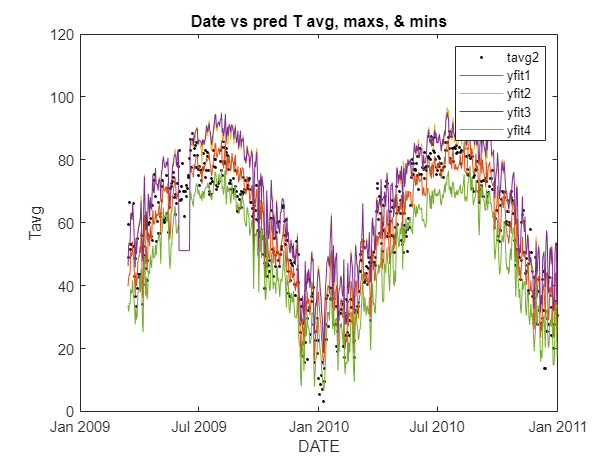


date = ws2.DATE;tavg2 = ws2.TAVG_2;

plot(date,tavg2,'k.',date,yft1,date,yft2,date,yft3,date,yft4)
legend('tavg2','yfit1','yfit2','yfit3','yfit4');title("Date vs pred T avg, maxs, & mins");xlabel("DATE");ylabel("Tavg");

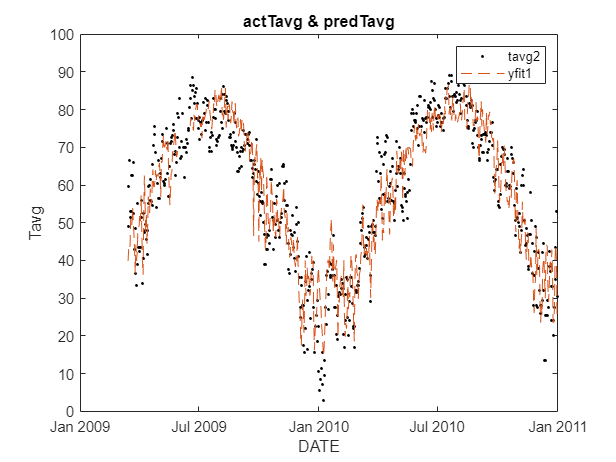


plot(date,tavg2,'k.',date,yft1,'--')
legend('tavg2','yfit1');title("actTavg & predTavg");xlabel("DATE");ylabel("Tavg");

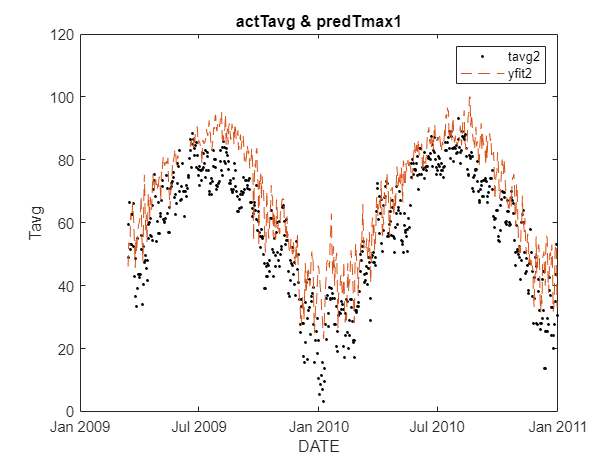


plot(date,tavg2,'k.',date,yft2,'--')
legend('tavg2','yfit2');title("actTavg & predTmax1");xlabel("DATE");ylabel("Tavg");

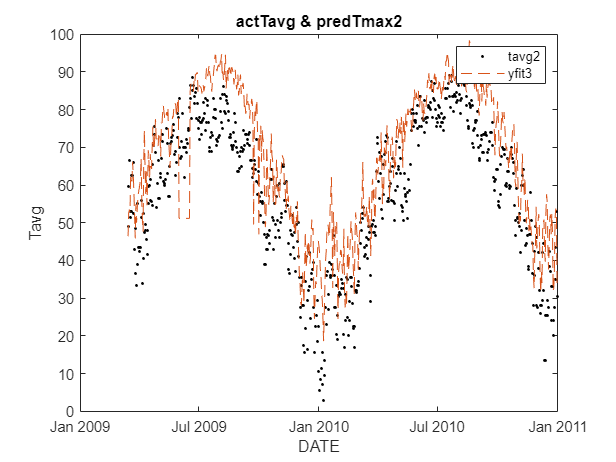


plot(date,tavg2,'k.',date,yft3,'--')
legend('tavg2','yfit3');title("actTavg & predTmax2");xlabel("DATE");ylabel("Tavg");

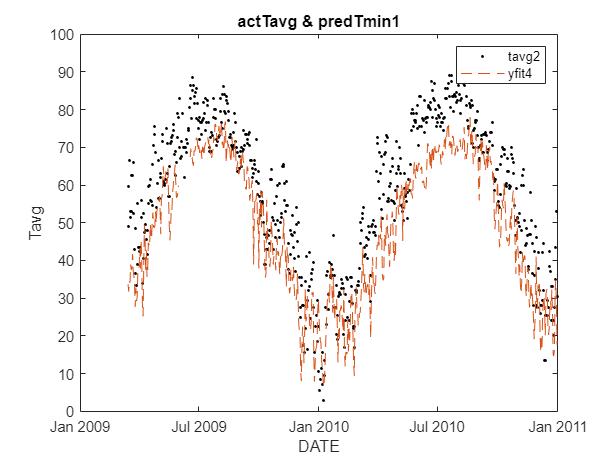


plot(date,tavg2,'k.',date,yft4,'--')
legend('tavg2','yfit4');title("actTavg & predTmin1");xlabel("DATE");ylabel("Tavg");

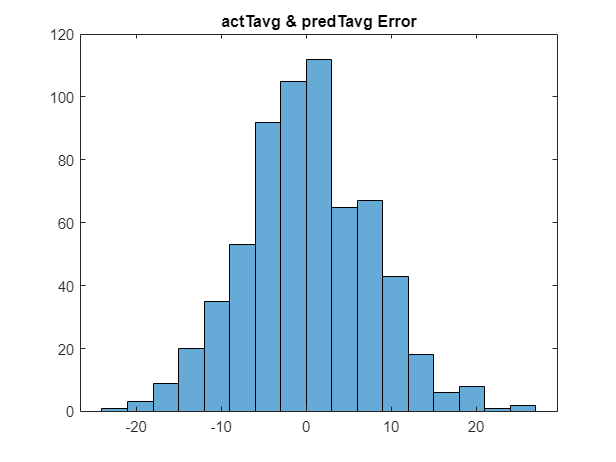


% Yfit Prediction Error: histogram
histogram(yft1-tavg2)
title("actTavg & predTavg Error");

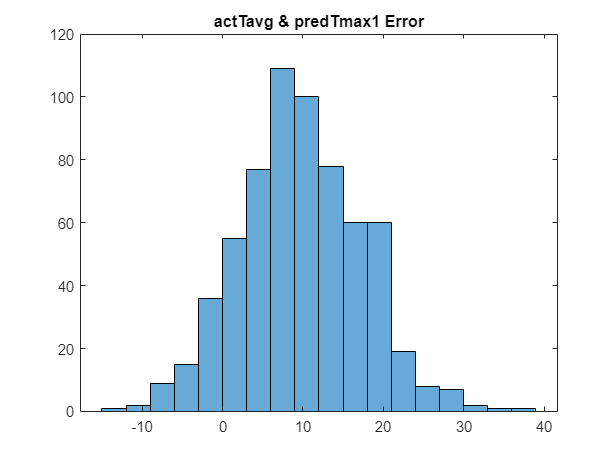

histogram(yft2-tavg2)
title("actTavg & predTmax1 Error");

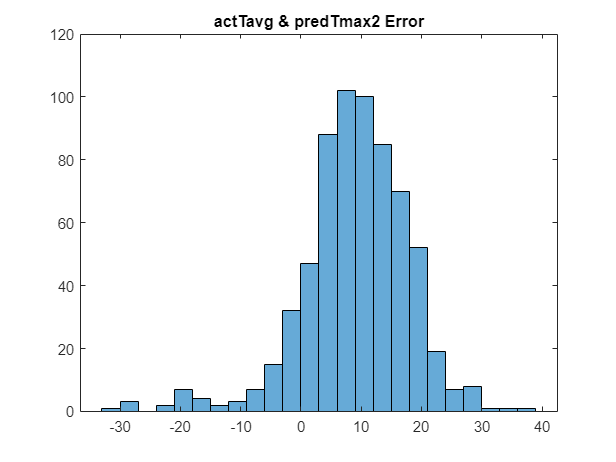

histogram(yft3-tavg2)
title("actTavg & predTmax2 Error");

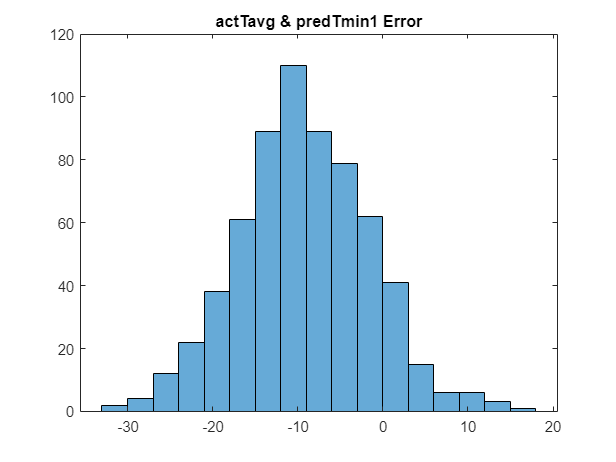

histogram(yft4-tavg2)
title("actTavg & predTmin1 Error");

% Above is the main function. Below is some experimental tinkering with
% averages. 
% With a series of averaging, I can marginally improve a fraction of the
% RMSE, but I wouldn't count on it 100% of the time.
% The results are not significant, but I still think there is an
% underlying pattern

 
% Averages of different yfits
y23 = (yft2+yft3)./2;      %tmax 1 & 2
y24 = (yft2+yft4)./2;      %tmax 1 & tmin 1
y25 = (yft2+yft5)./2;      %tmax 1 & tmin 2
y34 = (yft3+yft4)./2;      %tmax 2 & tmin 1
y35 = (yft3+yft5)./2;      %tmax 2 & tmin 2
y45 = (yft4+yft5)./2;      %tmin 1 & 2

% Actual T with averages
d2 = [tavg2,y23,y24,y25,y34,y35,y45]

d2 =    49.0000   46.2108   39.8767   39.9865   40.0224   40.1322   33.7981
   59.5000   53.1848   42.7207   42.8353   42.2247   42.3392   31.8751
   66.5000   53.3555   43.8416   43.8495   43.9826   43.9905   34.4766
   53.0000   52.6902   43.3768   43.5455   43.4218   43.5906   34.2772
   51.5000   62.6884   50.8646   50.5340   50.7538   50.4232   38.5993
   53.0000   61.3874   49.2350   49.5037   49.5825   49.8512   37.6988
   62.5000   61.2728   49.8712   49.7712   49.5345   49.4345   38.0329
   62.5000   66.2497   54.0246   53.8676   53.9411   53.7841   41.5590
   66.0000   62.7616   49.9995   50.3329   49.7452   50.0787   37.3165
   52.5000   58.2975   47.2743   47.4663   46.9467   47.1386   36.1154


%error
e2 = [tavg2,y23-tavg2,y24-tavg2,y25-tavg2,y34-tavg2,y35-tavg2,y45-tavg2]

e2 =    49.0000   -2.7892   -9.1233   -9.0135   -8.9776   -8.8678  -15.2019
   59.5000   -6.3152  -16.7793  -16.6647  -17.2753  -17.1608  -27.6249
   66.5000  -13.1445  -22.6584  -22.6505  -22.5174  -22.5095  -32.0234
   53.0000   -0.3098   -9.6232   -9.4545   -9.5782   -9.4094  -18.7228
   51.5000   11.1884   -0.6354   -0.9660   -0.7462   -1.0768  -12.9007
   53.0000    8.3874   -3.7650   -3.4963   -3.4175   -3.1488  -15.3012
   62.5000   -1.2272  -12.6288  -12.7288  -12.9655  -13.0655  -24.4671
   62.5000    3.7497   -8.4754   -8.6324   -8.5589   -8.7159  -20.9410
   66.0000   -3.2384  -16.0005  -15.6671  -16.2548  -15.9213  -28.6835
   52.5000    5.7975   -5.2257   -5.0337   -5.5533   -5.3614  -16.3846



% Error Averages
m23 = mean(y23-tavg2,"all","omitnan");m24 = mean(y24-tavg2,"all","omitnan");m25 = mean(y25-tavg2,"all","omitnan");
m34 = mean(y34-tavg2,"all","omitnan");m35 = mean(y35-tavg2,"all","omitnan");m45 = mean(y45-tavg2,"all","omitnan");

%RMSE %rmse = sqrt(sum((Y - evaluate(model,X)).^2)/N)
RMSE23 = sqrt((sum((y23-tavg2).^2,"all","omitnan"))./657);RMSE23m = sqrt((sum(((y23-m23)-tavg2).^2,"all","omitnan"))./657);
RMSE24 = sqrt((sum((y24-tavg2).^2,"all","omitnan"))./657);RMSE24m = sqrt((sum(((y24-m24)-tavg2).^2,"all","omitnan"))./657);
RMSE25 = sqrt((sum((y25-tavg2).^2,"all","omitnan"))./657);RMSE25m = sqrt((sum(((y25-m25)-tavg2).^2,"all","omitnan"))./657);
RMSE34 = sqrt((sum((y34-tavg2).^2,"all","omitnan"))./657);RMSE34m = sqrt((sum(((y34-m34)-tavg2).^2,"all","omitnan"))./657);
RMSE35 = sqrt((sum((y35-tavg2).^2,"all","omitnan"))./657);RMSE35m = sqrt((sum(((y35-m35)-tavg2).^2,"all","omitnan"))./657);
RMSE45 = sqrt((sum((y45-tavg2).^2,"all","omitnan"))./657);RMSE45m = sqrt((sum(((y45-m45)-tavg2).^2,"all","omitnan"))./657);


PredictionRMSE = table(RMSE23,RMSE24,RMSE25,RMSE34,RMSE35,RMSE45);
PredictionRMSE.Properties.VariableNames = {'RMSE23','RMSE24','RMSE25','RMSE34','RMSE35','RMSE45'}

PredictionRMSE = 1×6 table
    RMSE23    RMSE24    RMSE25    RMSE34    RMSE35    RMSE45
    ______    ______    ______    ______    ______    ______

    12.192    7.3878    7.3308    7.3592    8.9049    11.741



Predictions = table(tavg2,y23,y24,y25,y34,y35,y45);
Predictions.Properties.VariableNames = {'Tavg','pred23','pred24','pred25','pred34','pred35','pred45'}

Predictions = 657×7 table
    Tavg    pred23    pred24    pred25    pred34    pred35    pred45
    ____    ______    ______    ______    ______    ______    ______

      49    46.211    39.877    39.986    40.022    40.132    33.798
    59.5    53.185    42.721    42.835    42.225    42.339    31.875
    66.5    53.356    43.842     43.85    43.983     43.99    34.477
      53     52.69    43.377    43.546    43.422    43.591    34.277
    51.5    62.688    50.865    50.534    50.754    50.423    38.599
      53    61.387    49.235    49.504    49.583    49.851    37.699
    62.5    61.273    49.871    49.771    49.534    49.434    38.033
    62.5     66.25    54.025    53.868    53.941    53.784    41.559
      66    62.762    49.999    50.333    49.


PredictionError = table(tavg2,y23-tavg2,y24-tavg2,y25-tavg2,y34-tavg2,y35-tavg2,y45-tavg2);
PredictionError.Properties.VariableNames = {'Tavg','Error23','Error24','Error25','Error34','Error35','Error45'}

PredictionError = 657×7 table
    Tavg    Error23     Error24     Error25     Error34     Error35     Error45
    ____    ________    ________    ________    ________    ________    _______

      49     -2.7892     -9.1233     -9.0135     -8.9776     -8.8678    -15.202
    59.5     -6.3152     -16.779     -16.665     -17.275     -17.161    -27.625
    66.5     -13.144     -22.658      -22.65     -22.517      -22.51    -32.023
      53    -0.30984     -9.6232     -9.4545     -9.5782     -9.4094    -18.723
    51.5      11.188    -0.63544    -0.96605    -0.74623     -1.0768    -12.901
      53      8.3874      -3.765     -3.4963     -3.4175     -3.1488    -15.301
    62.5     -1.2272     -12.629     -12.729     -12.966     -13.066    -24.467
    62.5   

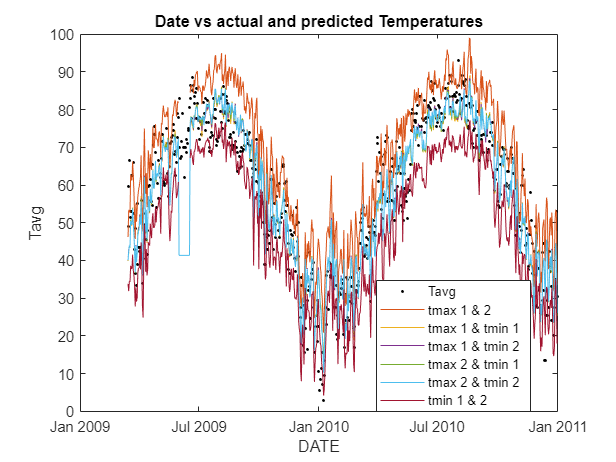




plot(date,tavg2,'k.',date,y23,date,y24,date,y25,date,y34,date,y35,date,y45)
title("Date vs actual and predicted Temperatures");xlabel("DATE");ylabel("Tavg");
legend('Tavg','tmax 1 & 2','tmax 1 & tmin 1','tmax 1 & tmin 2','tmax 2 & tmin 1','tmax 2 & tmin 2','tmin 1 & 2')

legend('Position',[0.61439,0.11681,0.24107,0.26667]);



% Outlier data tip - Skews the predictions just before July 2009
% ax = gca;chart = ax.Children(7);datatip(chart,datetime(2009,6,9,0,0,0),62);


 
y2324 = (y23+y24)./2;y2325 = (y23+y25)./2;y2334 = (y23+y34)./2;y2335 = (y23+y35)./2;
y2345 = (y23+y45)./2;y2425 = (y24+y25)./2;y2434 = (y24+y34)./2;y2435 = (y24+y35)./2;
y2445 = (y24+y45)./2;y2534 = (y25+y34)./2;y2535 = (y25+y35)./2;y2545 = (y25+y45)./2;
y3435 = (y34+y35)./2;y3445 = (y34+y45)./2;y3545 = (y35+y45)./2;

Y23 = [y2324,y2325,y2334,y2335,y2345];Y24 = [y2425,y2434,y2435,y2445];
Y25 = [y2534,y2535,y2545];Y34 = [y3435,y3445,y3545];

RMSE2324 = sqrt((sum((y2324-tavg2).^2,"all","omitnan"))./657);RMSE2325 = sqrt((sum((y2325-tavg2).^2,"all","omitnan"))./657);
RMSE2334 = sqrt((sum((y2334-tavg2).^2,"all","omitnan"))./657);RMSE2335 = sqrt((sum((y2335-tavg2).^2,"all","omitnan"))./657);
RMSE2345 = sqrt((sum((y2345-tavg2).^2,"all","omitnan"))./657);RMSE2425 = sqrt((sum((y2425-tavg2).^2,"all","omitnan"))./657);
RMSE2434 = sqrt((sum((y2434-tavg2).^2,"all","omitnan"))./657);RMSE2435 = sqrt((sum((y2435-tavg2).^2,"all","omitnan"))./657);
RMSE2445 = sqrt((sum((y2445-tavg2).^2,"all","omitnan"))./657);RMSE2534 = sqrt((sum((y2534-tavg2).^2,"all","omitnan"))./657);
RMSE2535 = sqrt((sum((y2535-tavg2).^2,"all","omitnan"))./657);RMSE2545 = sqrt((sum((y2545-tavg2).^2,"all","omitnan"))./657);
RMSE3435 = sqrt((sum((y3435-tavg2).^2,"all","omitnan"))./657);RMSE3445 = sqrt((sum((y3445-tavg2).^2,"all","omitnan"))./657);
RMSE3545 = sqrt((sum((y3545-tavg2).^2,"all","omitnan"))./657);


PredictionRMSE = table(RMSE2324,RMSE2325,RMSE2334,RMSE2335,RMSE2345,RMSE2425,RMSE2434,RMSE2435...
    ,RMSE2445,RMSE2534,RMSE2535,RMSE2545,RMSE3435,RMSE3445,RMSE3545);
PredictionRMSE.Properties.VariableNames = {'r2324','r2325','r2334','r2335','r2345','r2425','r2434','r2435',...
    'r2445','r2534','r2535','r2545','r3435','r3445','r3545'}

PredictionRMSE = 1×15 table
    r2324     r2325     r2334     r2335     r2345     r2425     r2434     r2435     r2445     r2534     r2535    r2545     r3435     r3445     r3545 
    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    _____    ______    ______    ______    ______

    8.8893    8.8863    8.8849    8.8867    7.3426    7.3562    7.3687    7.3426    8.6047    7.3426    7.323    8.5638    7.3389    8.5896    8.5535



Predictions = table(tavg2,y2324,y2325,y2334,y2335,y2345,y2425,y2434,y2435,y2445,y2534,y2535,y2545,...
    y3435,y3445,y3545);
Predictions.Properties.VariableNames = {'Tavg','y2324','y2325','y2334','y2335','y2345','y2425',...
    'y2434','y2435','y2445','y2534','y2535','y2545','y3435','y3445','y3545'}

Predictions = 657×16 table
    Tavg    y2324     y2325     y2334     y2335     y2345     y2425     y2434     y2435     y2445     y2534     y2535     y2545     y3435     y3445     y3545 
    ____    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

      49    43.044    43.099    43.117    43.171    40.004    39.932     39.95    40.004    36.837    40.004  

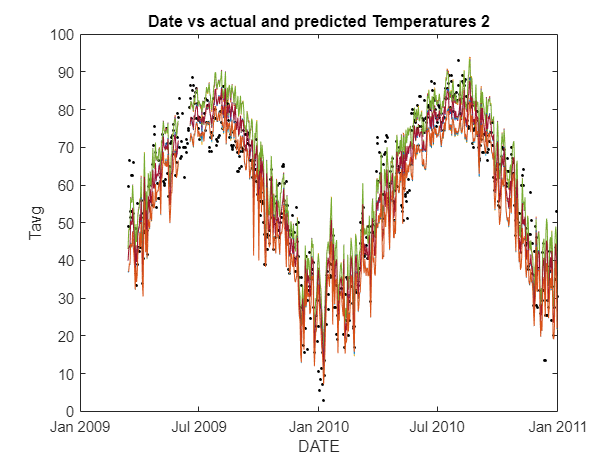


plot(date,tavg2,'k.',date,y2324,date,y2325,date,y2334,date,y2335,date,y2345,date,y2425,date,y2434,...
    date,y2435,date,y2445,date,y2534,date,y2535,date,y2545,date,y3435,date,y3445,date,y3545)
title("Date vs actual and predicted Temperatures 2");xlabel("DATE");ylabel("Tavg");

 
% Y averages verses smooth Tavg
Y = (y2324+y2325+y2334+y2335+y2345+y2425+y2434+y2435+y2445+y2534+y2535+y2545+y3435+y3445+y3545)./15;
tavg2 = smooth(tavg2);

tavg2 =    49.0000
   58.3333
   55.9000
   56.7000
   57.3000
   56.5000
   59.1000
   59.3000
   57.3000
   54.5000


differenceY = Y-tavg2;
dataY = table(tavg2,Y,differenceY)

dataY = 657×3 table
    tavg2       Y       differenceY
    ______    ______    ___________

        49    40.004      -8.9956  
    58.333     42.53      -15.803  
      55.9    43.916      -11.984  
      56.7    43.484      -13.216  
      57.3    50.644      -6.6561  
      56.5    49.543      -6.9569  
      59.1    49.653      -9.4472  
      59.3    53.904      -5.3957  
      57.3    50.039      -7.2609  
      54.5    47.206      -7.2935  
      49.3    42.605      -6.6955  
      42.8    36.766      -6.0342  
      40.1    44.001        3.901  
      42.5    39.693      -2.8067  
      41.5    42.076      0.57623  
      42.9    46.961        4.061  


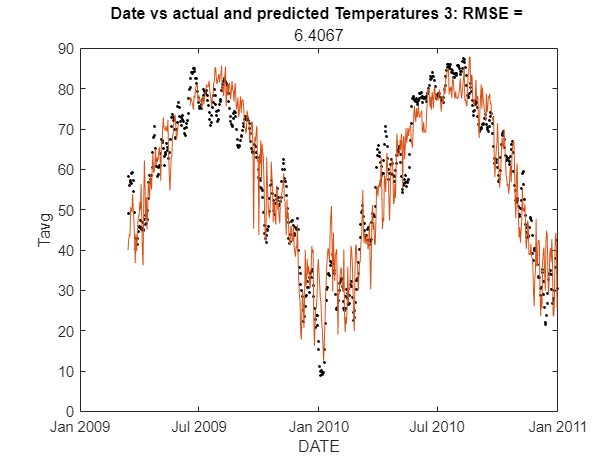

RMSEY = sqrt((sum((Y-tavg2).^2,"all","omitnan"))./657);

plot(date,tavg2,'k.',date,Y)
title("Date vs actual and predicted Temperatures 3: RMSE = ",RMSEY);xlabel("DATE");ylabel("Tavg");


% Outlier data tip - Skews the predictions just before July 2009
% ax = gca;chart = ax.Children(7);datatip(chart,datetime(2009,6,9,0,0,0),62);

%predictTavg = trainedModel.predictFcn(w)
